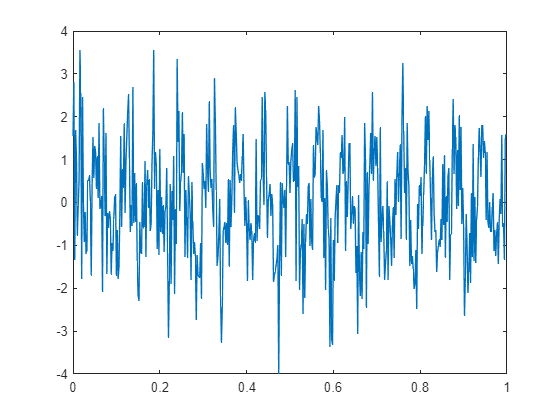

Fs = 500;
N = 500;
rng default
n = (0:N-1)/ Fs;
x = cos(100*n) +  randn(1, N);
plot(n, x)

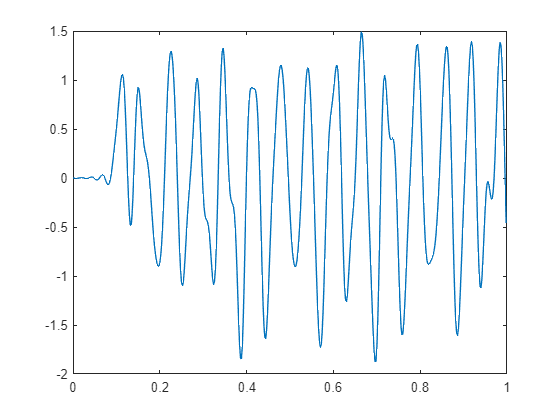

df = designfilt('lowpassfir', 'FilterOrder', 100, 'CutoffFrequency', 40, 'Samplerate', 500, 'Window', 'hamming');
y = filter(df, x);
plot(n, y)

D = mean(grpdelay(df))

D = 50

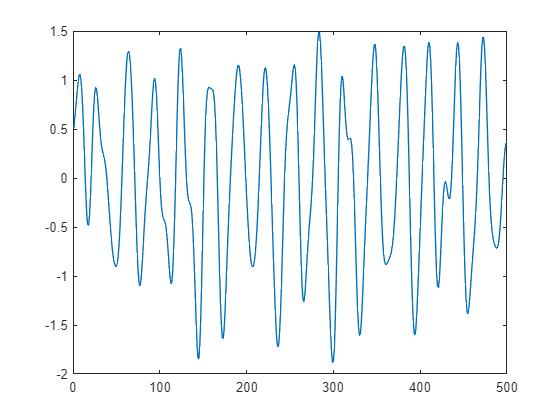

y = filter(df, [x zeros(1, D)]);
y = y(D+1:end);
plot(y)

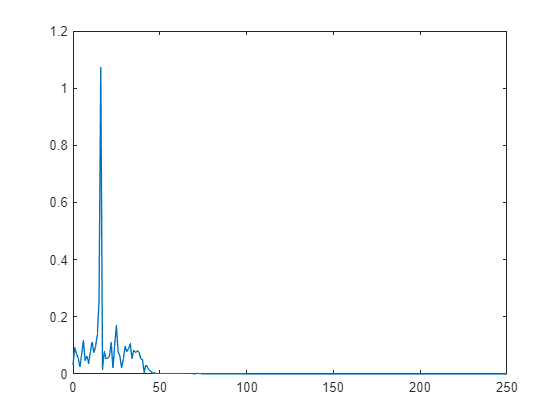

X = fft(y);
%L = 430242;
L = N;
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1)